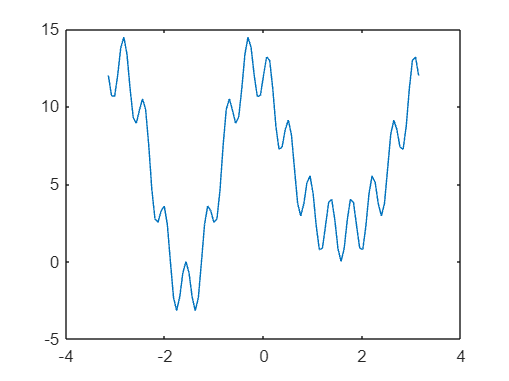

PL = 9;
A1 = 2*(mod(PL,2)+1);
A2 = 6*(mod(PL,2)+1);
wa=mod(PL,5)+2;
wb=mod(PL,7)+7;
wc=mod(PL,9)+1;

syms t
x1 = A1*sin(wa*t)*cos(wb*t)+A2*cos(wc*t)^2;
ti = -pi;
tf = pi;
tplot = ti:(tf-ti)/100:tf;
plot(tplot, double(subs(x1, tplot)));


%Exercicio 2

x = trapesio(x1,ti,tf,10);
x

x = 37.6991


y = simpson(x1,ti,tf,10);
y

y = 37.6991


z = energia(x1, 0.1);

Not enough input arguments.

Error in Ficha2>energia (line 42)
    t = ti:ts:tf;

z



function res = trapesio(f, ti, tf, nInt)
    h = (tf-ti)/nInt;
    t = ti:h:tf;
    ft = double(subs(f,t));
    res = ((ft(1) + ft(end))/2 + sum(ft(2:end-1)))*h;
end

function res = simpson(f, ti, tf, nInt)
    h = (tf-ti)/nInt;
    t = ti:h:tf;
    ft = double(subs(f,t));
    res = (h/3)*(ft(1) + ft(end) + 4 * sum(ft(2:2:end-1)) + 2 * sum(ft(3:2:end-1)));
end

function res = energia(f, ti, tf, ts)
    t = ti:ts:tf;
    res = sum(obs(f(t))) * ts;
end